clear;close all
n=1000;p=1;m=100;
% xx=Tent_x(n,p);
xx=Logistic_x(4,n,p);
[~,~,U,K,~,x_marker] = Tent_U_Rectangle_leftU(xx,m);
% [~,~,U,K,~,x_marker] = Tent_U_Gauss_leftU(xx,m);

A=U';
% A=[.5,.5,0,0;0,0,.5,.5;0,0,.5,.5;.5,.5,0,0];
[mm,nn]=size(A);
lambda=0;
miu=0.1;N=1;
full_x=@(x)[x;1-norm(x,N)];
f=@(x)norm(A*full_x(x)-lambda*full_x(x))+miu*norm(diff(full_x(x)),N);

x0=rand(mm-1,1);yita=0.001;iter=1000;
x=fmin_GD(f,x0,yita,iter)

x =    -0.0009
   -0.0007
   -0.0005
    0.0672
   -0.0005
   -0.0006
   -0.0005
    0.1339
    0.0448
   -0.0005


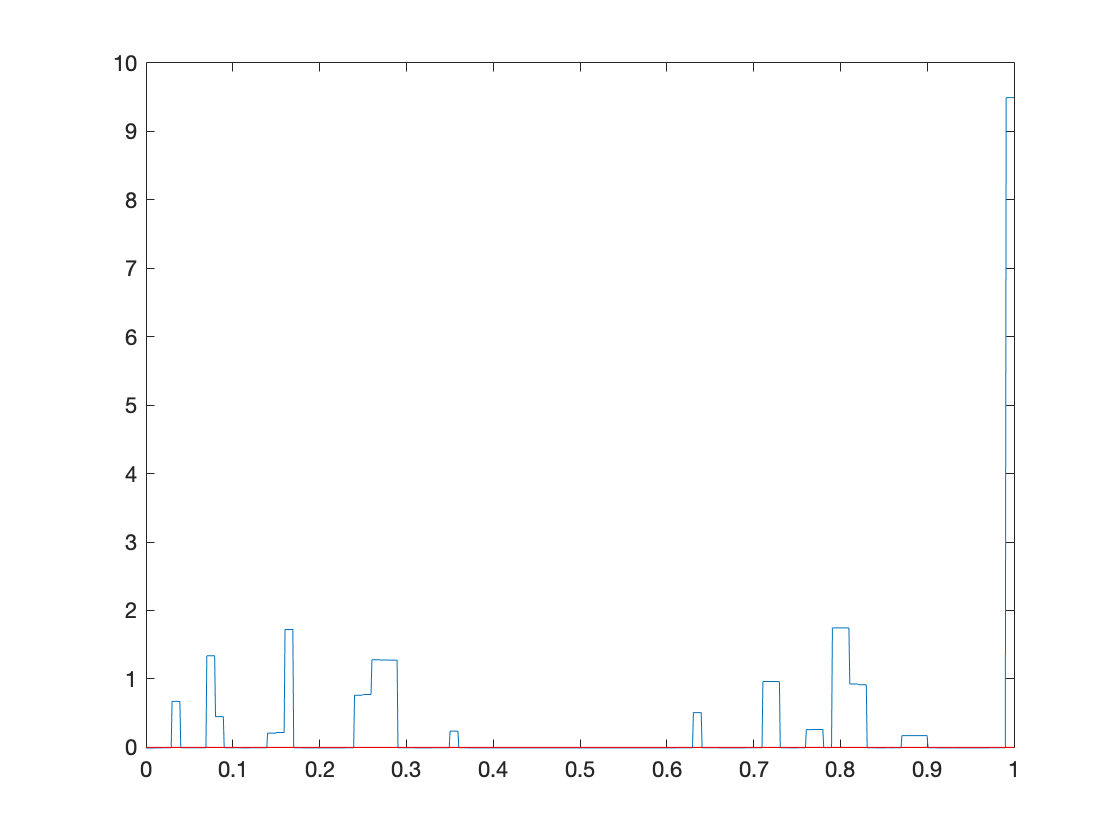


pA=real(K*full_x(x));
figure
%subplot(121)
%set(gcf,'outerposition',get(0,'screensize'));
x0=linspace(0,1,n);
hh=plot(x0,pA);
hold on
plot([0,1],[0,0],'r')

%title(['\mu=',num2str(miu),',\lambda=0,fval=',num2str(fval),',flag=',num2str(exitflag)])

%

function x=fmin_GD(f,x0,yita,iter)
    x=x0;
    %disp(x);
for i=1:iter
    dx=zeros(length(x0),1);
    for j=1:length(x0)
        dx(j)=DFx(f,x,j,0.001);
    end
    x=x-yita*dx;
end
end

function dx=DFx(f,x,i,delta_x)
dx=(f(x+[zeros(i-1,1);delta_x;zeros(length(x)-i,1)])-f(x))/delta_x;
end

function X=Logistic_x(alpha,n,p)
x0=linspace(0,1,n);  
f=@(x)alpha.*x.*(1-x);
X=x0;
x=x0;
for i=1:p
    x=f(x);
    X=[X;x];
end
end

function [F,D,U,K,L,x0]= Tent_U_Rectangle_leftU(x,m,flag)
x_k=x(1,:);
x_l=x(end,:);
x0=linspace(1/2/m,1-1/2/m,m);
if nargin<3
    K=Logistic_G_Rectangle(x_k,m);
    L=Logistic_G_Rectangle(x_l,m);
else
    K=Logistic_G_Rectangle_natural(x_k,m);
    L=Logistic_G_Rectangle_natural(x_l,m);
end
U=pinv(K)*L;
[F,D]=eig(U);
D=diag(D);
end

function G= Logistic_G_Rectangle(x,m)
G=zeros(length(x),m);
x=x(:);
for i=1:m-1
    G(:,i)=(x>=(i-1)/m & x<i/m)*sqrt(m);
end
G(:,m)=(x>=(m-1)/m & x<=m/m)*sqrt(m);
end

function G=Logistic_G_Rectangle_natural(x,m)
x_function=Logistic_x(4,m+1,1);
x_function(2,:);
for i=1:m-1
    G(:,i)=(x>=x_function(2,i) & x<x_function(2,i+1)) * sqrt(1/(x_function(2,i+1)-x_function(2,i)));
end
i=m;
G(:,i)=(x>=x_function(2,i) & x<x_function(2,i+1)) * sqrt(1/(x_function(2,i+1)-x_function(2,i)));
end